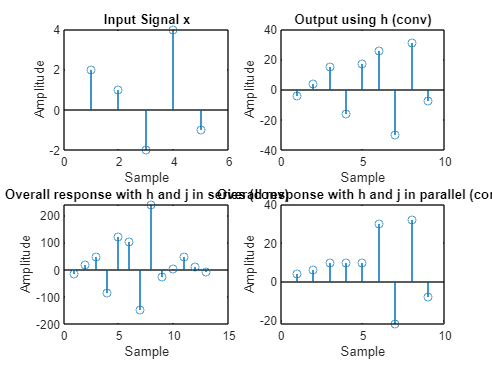

% Input signal
x = [2, 1, -2, 4, -1];

% System h
h = [-2, 3, 4, -3, 7];

% System j
j = [4, -1, 2, 3, 1];

% System k
k = [6, 5, 4, 3, 2];

% Convolution with h using conv command
y1 = conv(x, h);

% Overall response with h and j in series (conv)
hj = conv(h, j);
y2 = conv(x, hj);

% j in parallel with h, then series with x (conv)
hj_parallel = h + j;
y3 = conv(x, hj_parallel);

% h and j in series
hj_series = conv(h,j);

% Zero-pad the shorter vector (k) to match hj_series length
k_padded = [k, zeros(1, length(hj_series) - length(k))];

% Combine hj_series and k_padded (effectively parallel connection)
result = hj_series + k_padded;

% Series with x (conv)
y4 = conv(x, result);

% Plot results separately
figure;
subplot(221);
stem(x);
title('Input Signal x');
xlabel('Sample');
ylabel('Amplitude');

subplot(222);
stem(y1);
title('Output using h (conv)');
xlabel('Sample');
ylabel('Amplitude');

subplot(223);
stem(y2);
title('Overall response with h and j in series (conv)');
xlabel('Sample');
ylabel('Amplitude');

subplot(224);
stem(y3);
title('Overall response with h and j in parallel (conv)');
xlabel('Sample');
ylabel('Amplitude');

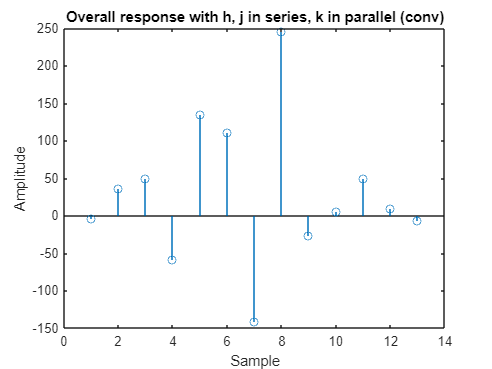


figure;
stem(y4);
title('Overall response with h, j in series, k in parallel (conv)');
xlabel('Sample');
ylabel('Amplitude');